# Distributed Coding Live Script - Single Trial All Neurons

## Setup

### MatNWB

Start by setting up your MATLAB workspace. The code below clones the MatNWB repo to the current directory and adds the folder ontaining the MatNWB package to the MATLAB search path. MatNWB works by automatically creating API classes based on a defined schema. Running the generateCore() function generates these classes for the lastest schema version.

!git clone https://github.com/NeurodataWithoutBorders/matnwb.git
cd ./matnwb
addpath(genpath(pwd));
generateCore();
cd ..

### distributed-coding-matnwb

You will also need the distributed-coding-matnwb repo, which has some useful plotting function

!git clone https://github.com/catalystneuro/distributed-coding-matnwb.git
cd ./distributed-coding-matnwb
addpath(genpath(pwd));
generateCore();
cd ..

### DANDIset

Download the relevant [DANDIset](https://dandiarchive.org/dandiset/000017/draft)

## Load in file

% path to file, change to desired file
DANDIset_folder = '~/DANDIsets/000017/';
filepath = [DANDIset_folder 'sub-Moniz/sub-Moniz_ses-20170515T120000.nwb'];
% read in file
nwb_file = nwbRead(filepath);
% display number of trials
ntrials = length(nwb_file.intervals_trials.start_time.data(:));
fprintf('Total trials: %d\n', ntrials)

Total trials: 247


## Select trial and plot response

% recreate Figure 1j from Steinmetz, N. A., Zatka-Haas, P., Carandini, M., & Harris, K. D. (2019). Distributed coding of choice, action and engagement across the mouse brain. Nature, 576(7786), 266-273.

% Select trial
trial = 74;

% print trial info
infoTable = getTrialInfo(nwb_file, trial)

infoTable = 1×5 table
    Contrast Left    Contrast Right    Animal Choice       Feedback       Reaction Time
    _____________    ______________    _____________    ______________    _____________

          1                0             {'No-Go'}      {'Punishment'}       1.5026    


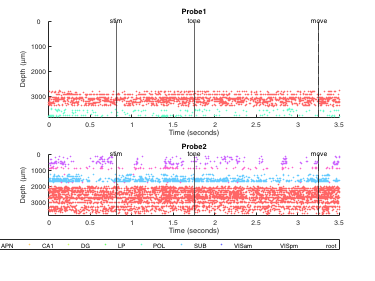

% output raster plot figure
 
plotRastersAllUnits(nwb_file, trial)